# Résolution d'un problème d'optimisation linéaire avec Matlab

Soit un problème simple de gestion d'energie incluant une batterie et une source PV. On utilise la toolbox YALMIP pour modéliser le problème et le solveur CPLEX pour le résoudre.

**Data :  **

- Puissance PV au pas horaire : $p_t^{ld}$

- Puissance elec au pas horaire : $p_t^{pv}$  

- Coût de la fourniture élec : $c_t^{g,+}$

**Variable de controle :  **

- Puissance de la batterie : $u_t=(p_t^b)$  

**Variable d'état :  **

- Etat de charge de la batterie : $x_t=(soc_t^b)$  

**Variable de recours :  **

- Puissance du réseau externe : $p_t^g$   

**Objectif :  **

- Minimiser la facture en supposant qu'on ne peut pas re-injecter sur le reseau ( $p_t^{g,+} \ge 0$ ) : 

 
$$\min_{u_t \in U_{ad}}  \sum_{t=1}^T p_t^{g,+}.c_t^{g,+}$$


## Chargement des paramètres

% -------------------------------------------------------------------------
% Paramètres de simulation
%--------------------------------------------------------------------------
dk = 1; % (h) pas de temps
horizon = 24; % (h) horizon
nk = length(dk:dk:horizon); % nombre de pas de temps

% -------------------------------------------------------------------------
% Data
%--------------------------------------------------------------------------
data_tuto = readtable("data_tuto.csv") % tableau de séries temporelles normalisées

data_tuto = 24×3 table
    data_ld_E     data_pv     pxGrid
    _________    _________    ______

    0.19928              0    0.1   
    0.19714              0    0.1   
     0.1961              0    0.1   
    0.20007              0    0.1   
    0.21283      0.0038314    0.1   
    0.24166       0.018764    0.1   
    0.28758       0.070853    0.1   
     0.3848        0.18369    0.1   
    0.49583        0.32953    0.2   
    0.54572        0.42921    0.2   
    0.52874        0.50631    0.2   
    0.48478        0.53036    0.2   
    0.45927        0.51491    0.2   
    0.47903         0.4384    0.2   
    0.50448        0.34819    0.2   
    0.51496         0.2036    0.2   


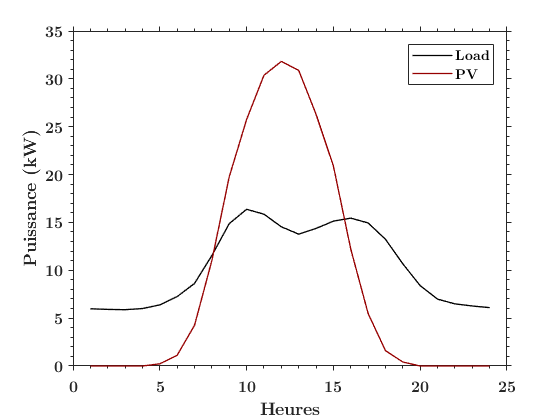


pv.pkWc = 60; % (kWc) puissance crête
pv.power = pv.pkWc * data_tuto.data_pv;

ld.pMax = 30; % puissance max électrique
ld.power = ld.pMax * data_tuto.data_ld_E;

% Plot des données 
plot(dk:dk:horizon,ld.power,'k',dk:dk:horizon,pv.power)
ylabel("Puissance (kW)")
xlabel("Heures")
legend("Load","PV")

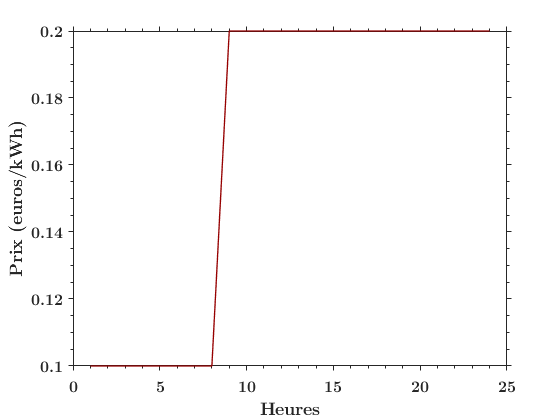


% -------------------------------------------------------------------------
% Batterie
%--------------------------------------------------------------------------
% Parametres
batt.Erated = 200; % (kWh) capacité
batt.pMaxCh = 300; % (kW) puissance max de charge
batt.pMaxDch = 300; % (kW) puissance max de décharge
batt.etaCh = 0.8; % (0-1) rendement de charge
batt.etaDch = 0.8; % (0-1) rendement de décharge
batt.socMin = 0.2; % (0-1) SOC min
batt.socMax = 0.8; % (0-1) SOC max
batt.socIni = 0.5; % (0-1) SOC initial

% Pre-allocation
batt.soc = zeros(nk+1,1);
batt.soc(1) = batt.socIni; 
batt.power = zeros(nk,1);

% -------------------------------------------------------------------------
% Grid
%--------------------------------------------------------------------------
grid.pxGrid = data_tuto.pxGrid; % prix de l'élec (€/kWh)
grid.pMax = 100; % puissance de soutirage max (fixé arbitrairement ici...)
grid.power = zeros(nk,1);

% Plot du profil de prix de l'électricité hp/hc
plot(dk:dk:horizon,grid.pxGrid)
ylabel("Prix (euros/kWh)")
xlabel("Heures")

## Simulation du micro-réseau

% Calcul de la trajectoire de controle sur l'horizon (le script de la fonction est à la fin du document)
controlPowerBatt = controlMILP(batt, grid, ld, pv, dk, nk);

% Simulation du micro-réseau sur l'horizon
for k=1:nk
    
    % Limitation en puissance
    batt.power(k) = max(min(0,controlPowerBatt(k)),-batt.pMaxCh) + min(max(0,controlPowerBatt(k)),batt.pMaxDch);
    
    % Dynamique de la batterie
    batt.soc(k+1)=batt.soc(k) - ( min(0,batt.power(k)) * batt.etaCh + max(0,batt.power(k)) / batt.etaDch ) * dk / batt.Erated;
    
    % Calcul de la puissance du réseau
    grid.power(k) = max(0,ld.power(k) - pv.power(k) - batt.power(k));
    
end

% NB : Le modèle utilisé pour la simulation peut être différent du modèle d'optimisation qui est souvent simplifié pour
% limiter les temps de calcul. Dans notre cas, les deux modèles sont identiques...

## **Plot des puissances et du SOC de la batterie**

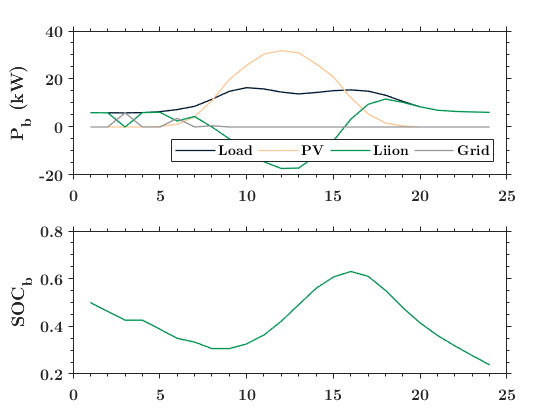


%% Plot
tPlot=dk:dk:horizon;

sp(1)=subplot(2,1,1);
p1=plot(tPlot,ld.power,'Color',[0 25 50]/255);
hold on
p2=plot(tPlot,pv.power,'Color',[255 200 150]/255);
hold on
p3=plot(tPlot,batt.power,'Color',[0 150 80]/255);
hold on
p4=plot(tPlot,grid.power,'Color',[150 150 150]/255);
hold on
ylabel('P_b (kW)')
legend([p1 p2 p3 p4],'Load','PV','Liion','Grid','Orientation','horizontal','Location','southeast')

sp(2)=subplot(2,1,2);
plot(tPlot,batt.soc(1:end-1),'Color',[0 150 80]/255)
ylabel('SOC_b')

## Calcul de la facture élec

facture = sum(grid.power .* grid.pxGrid) * dk

## Fonction de control MILP

Formulation du problème sous YALMIP et on utilise le solver CPLEX. Pour utiliser un autre solveur, modifier la commande dans "sdpsettings"...

function controlPowerBatt = controlMILP(batt, grid, ld, pv, dk, nk)
    
    % Variables
    soc=sdpvar(nk+1,1,'full');
    pCh_b=sdpvar(nk,1,'full');
    pDch_b=sdpvar(nk,1,'full');
    p_g=sdpvar(nk,1,'full');
    
    % Contraintes
    contraintes=[];
    
    contraintes=[contraintes, 0 <= pDch_b <= batt.pMaxDch];
    contraintes=[contraintes, -batt.pMaxCh <= pCh_b <= 0];
    
    contraintes=[contraintes, batt.socMin <= soc <= batt.socMax];
    contraintes=[contraintes, soc(1) == batt.socIni];
    
    for k=1:nk
        contraintes=[contraintes, soc(k+1) == soc(k) - (pCh_b(k) * batt.etaCh + pDch_b(k) / batt.etaDch) * dk / batt.Erated];
    end
    
    
    contraintes=[contraintes, 0 <= p_g <= grid.pMax];
    contraintes=[contraintes, ld.power - pv.power - pCh_b - pDch_b <= p_g ];
    
    % Objectif
    obj=(sum(p_g.*grid.pxGrid)).*dk;
    
    % Solve
    ops=sdpsettings('solver','cplex','verbose',0);
    optimize(contraintes,obj,ops);
    
    % Output
    controlPowerBatt = value(pCh_b + pDch_b);
    
end